nvar = 4; 
fun = @shekel_func; 
lb = [-15, -15, -15, -15]; 
ub = [20, 20, 20, 20]; 

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


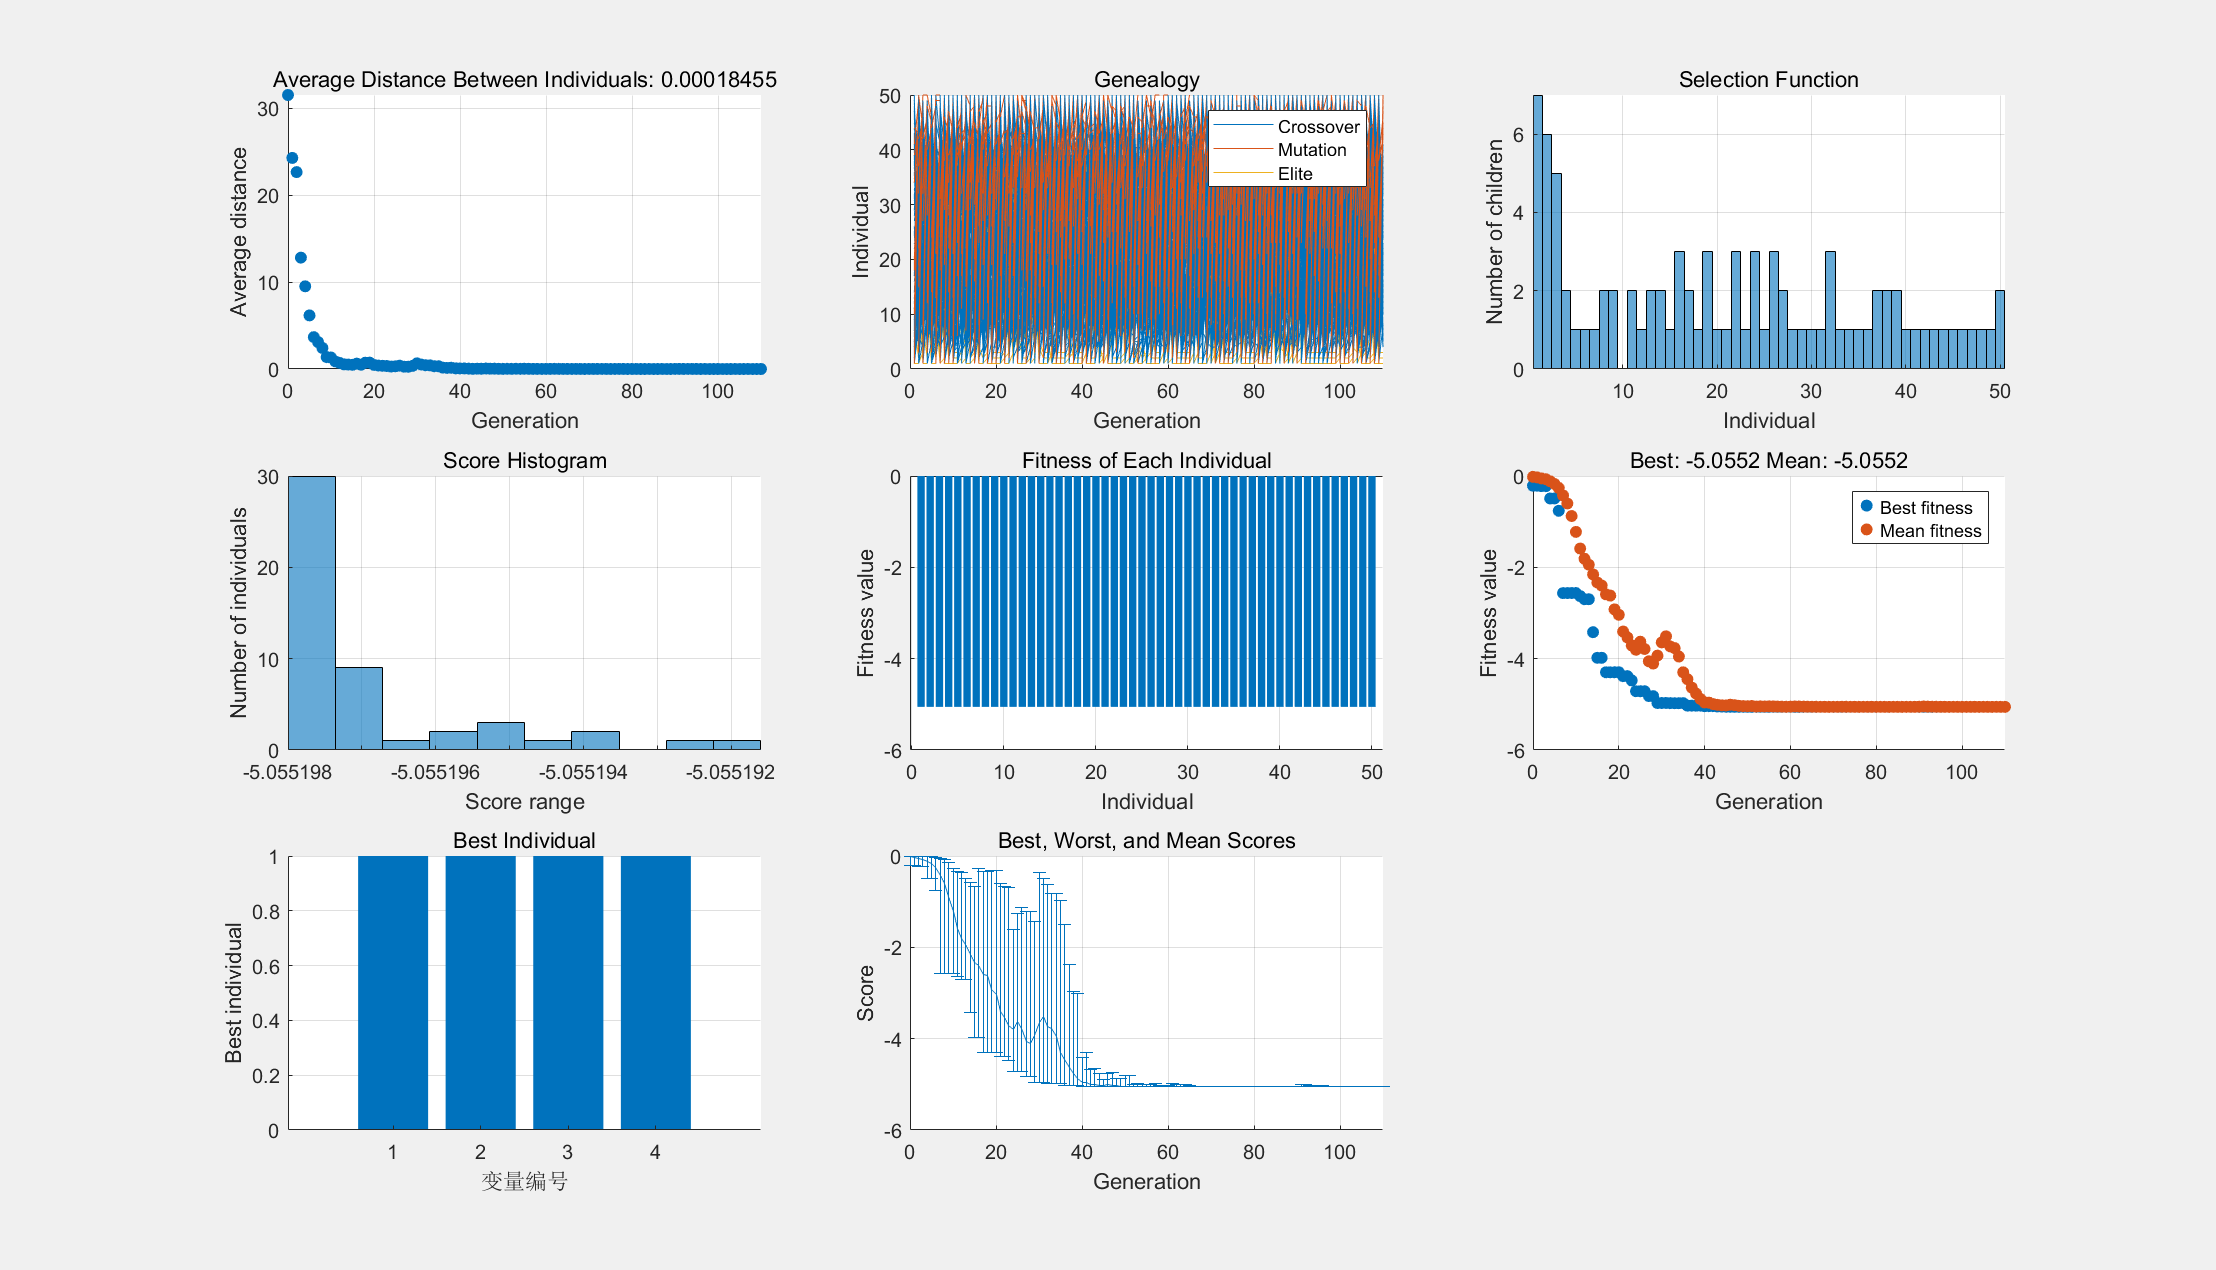

% 设置非默认求解器选项
options2 = optimoptions("ga","PlotFcn",["gaplotdistance","gaplotgenealogy",...
    "gaplotselection","gaplotscorediversity","gaplotscores","gaplotbestf",...
    "gaplotbestindiv","gaplotrange"]);

% 求解
[solution,objectiveValue] = ga(fun,nvar,[],[],[],[],repmat(-15,nvar,1),...
    repmat(20,nvar,1),[],[],options2);


% 清除变量
clearvars options2


disp(solution)

    1.0001    1.0002    1.0001    1.0001



disp(objectiveValue)

   -5.0552

